Øvelse af sampling og rekonstruktion, som set i PDF i SIG Lektion 2.

## **1. Ideel sampling og rekonstruktion**

**Definition af analogt signal:**

f_uendelig = 100000;
T_uendelig = 1/f_uendelig;
N = 1000;
n=0:N-1;
f1=1000;
x_analog = sin(2*pi*f1*n*T_uendelig);

Et analogt signal med en enkelt harmonisk er herved oprettet. Med analogt menes, at det er diskret men med meget høj samplingfrekvens.

**Plot af analogt signal i tid og frekvens:**

subplot(2,1,1)

plot(n,x_analog)

Frekvensspektret vises med fft-kommandoen (Fast Fourier-Transform)

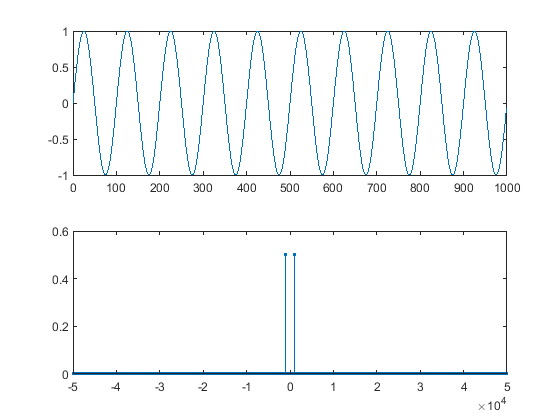

subplot(2,1,2)
X_analog = (1/N)*fftshift(fft(x_analog,N));
k = (-N/2):(N/2-1); %index-vektor
f=k*f_uendelig/N; %frekvens-vektor)
stem(f,abs(X_analog),'.')

**Definition af samplingssignal til ideel sampling:**

Samplingsfrekvens defineres

fs=10000; %1/10 af det "analoge" signal
Ts=1/fs;
%Modelleres ved at bruge et impulstog
sample_periode=[1 zeros(1,9)]; %En periode af impulstog er Ts=10*T_uendelig
impulstog=[];
for i = 1:100
    impulstog = [impulstog sample_periode];
end;

**Ideel sampling:**

Ideel sampling modelleres som en multiplikation af det analoge signal og impulstoget:

x_samplet = x_analog.*impulstog; %Punktummet giver elementmultiplikation

**Plot af analogt og samplet signal i tidsdomænet:**

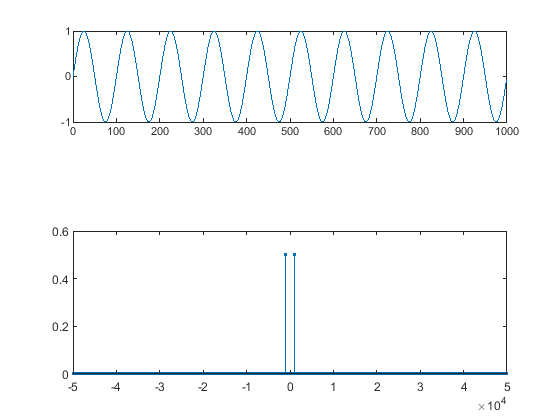

subplot(3,1,1)
plot(n,x_analog)

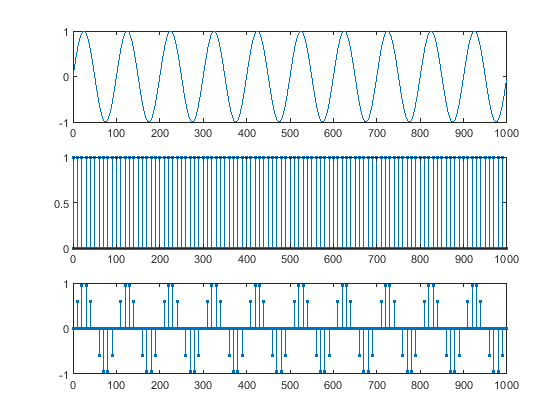

subplot(3,1,2)
stem(n,impulstog,'.')
subplot(3,1,3)
stem(n,x_samplet,'.')

**Plot af analogt og samplet signal i frekvensdomænet:**

Ved sampling udtages her hvert 10. sample.

Ved beregning af frekvensspektrum med FFT skal derfor skaleres med faktor 10 ved sammenligning af amplitude-værdier.

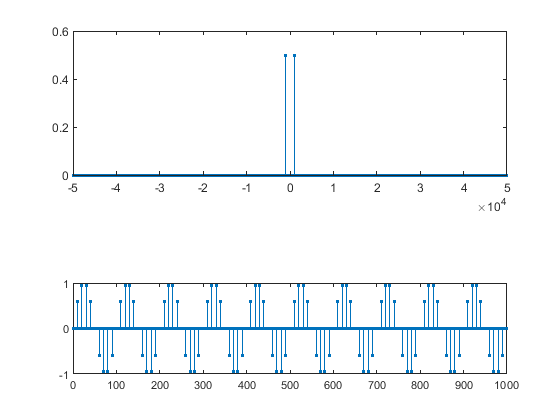

X_samplet = 10*(1/N)*fftshift(fft(x_samplet,N));
subplot(2,1,1)
stem(f,abs(X_analog),'.')

subplot(2,1,2)
stem(f,abs(X_samplet),'.')

**Definition af rekonstruktionslavpasfilter:**

Ved rekonstruktion anvendes et rekonstruktionslavpasfilter med en knækfrekvens på fs/2.

Kommandoer studeres ikke nærmere her, først i DSP.

help fir1

 fir1   FIR filter design using the window method.
    B = fir1(N,Wn) designs an N'th order lowpass FIR digital filter
    and returns the filter coefficients in length N+1 vector B.
    The cut-off frequency Wn must be between 0 < Wn < 1.0, with 1.0
    corresponding to half the sample rate.  The filter B is real and
    has linear phase.  The normalized gain of the filter at Wn is
    -6 dB.
 
    B = fir1(N,Wn,'high') designs an N'th order highpass filter.
    You can also use B = fir1(N,Wn,'low') to design a lowpass filter.
 
    If Wn is a two-element vector, Wn = [W1 W2], fir1 returns an
    order N bandpass filter with passband  W1 < W < W2. You can
    also specify B = fir1(N,Wn,'bandpass').  If Wn = [W1 W2],
    B = fir1(N,Wn,'stop') will design a bandstop filter.
 
    If Wn is a multi-element vector,
           Wn = [W1 W2 W3 W4 W5 ... WN],
    fir1<

filterorden = 200;
normeret_knaekfrekvens = (fs/2)/(f_uendelig/2);
rekonstr_filter=fir1(filterorden,normeret_knaekfrekvens);
freqz(rekonstr_filter,1,1024,f_uendelig); %Filteres frekvenskarakteristik kontrolleres

Dette er altså et ikke-ideelt digitalt filter.

**Ideel rekonstruktion:**

Rekonstruktion foretages ved at sende signal gennem lavpasfilter

x_rekonstr = filter(rekonstr_filter,1,x_samplet);

**Plot af samplet og rekonstrueret signal i tidsdomænet:**

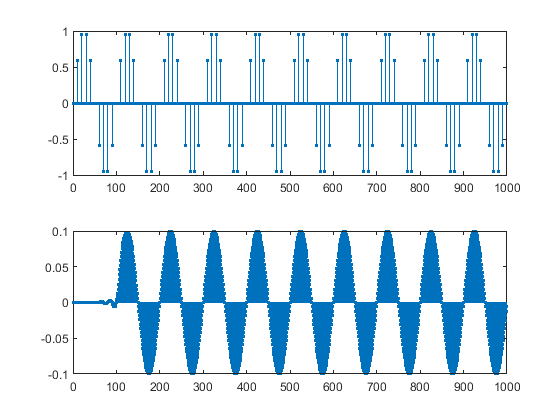

subplot(2,1,1)
stem(n,x_samplet,'.')
subplot(2,1,2)
stem(n,x_rekonstr,'.')

**Plot af analogt, samplet og rekonstureret signal i frekvensdomænet:**

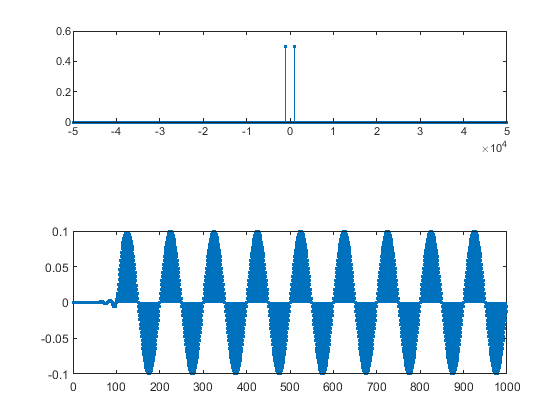

X_rekonstr = 10*(1/N)*fftshift(fft(x_rekonstr,N));
subplot(3,1,1)
stem(f,abs(X_analog),'.')

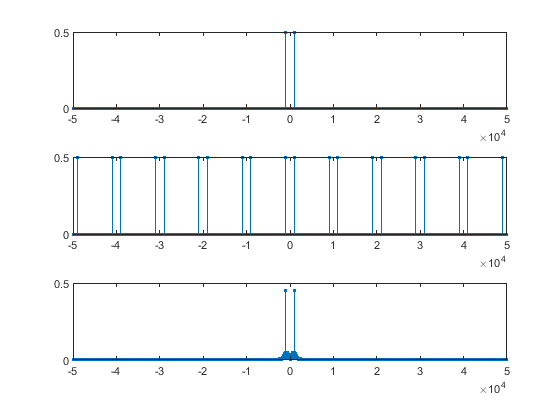

subplot(3,1,2)
stem(f,abs(X_samplet),'.')
subplot(3,1,3)
stem(f,abs(X_rekonstr),'.')

## 2. Aliasing

Der prøves igen med et nyt analogt signal

**Definition af analogt signal:**

f1 = 3000;
A1 = 2;
f2 = 6000;
A2 = 1;
f_uendelig = 100000;
T_uendelig = 1/f_uendelig;
fs = 10000;
Ts = 1/fs;
N = 1000;
n = 0:N-1;
x_analog = A1*sin(2*pi*f1*n*T_uendelig) + A2*sin(2*pi*f2*n*T_uendelig);

**Plot af analogt signal i tid og frekvens:**

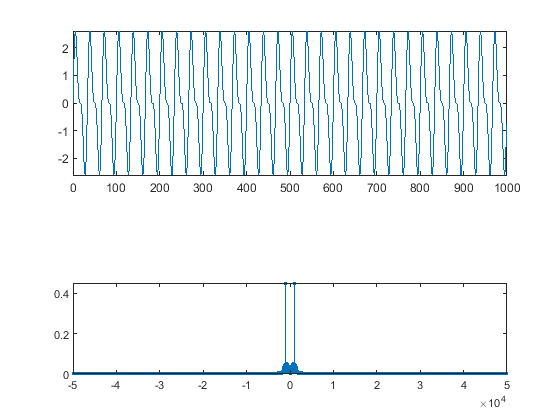

subplot(2,1,1)
plot(n,x_analog)

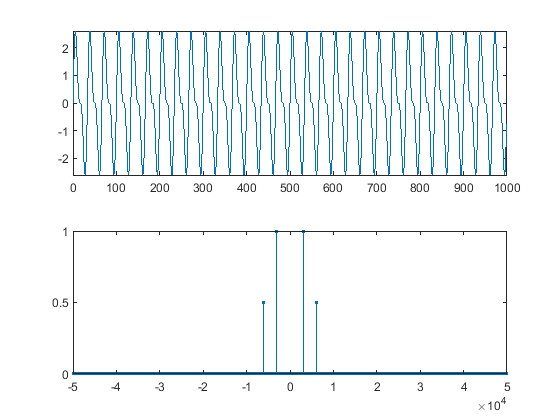

subplot(2,1,2)
X_analog=(1/N)*fftshift(fft(x_analog,N));
k = (-N/2):(N/2-1); %Index-vektor
f = k*f_uendelig/N; %Frekvens-vektor
stem(f,abs(X_analog),'.')

**Ideel sampling:**

x_samplet = x_analog.*impulstog;

**Plot af analogt og samplet signal i tidsdomænet:**

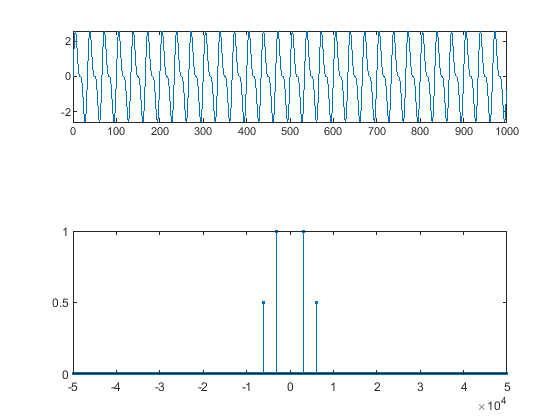

subplot(3,1,1)
plot(n,x_analog)

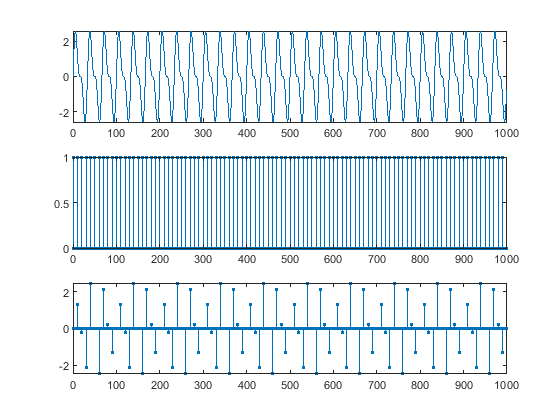

subplot(3,1,2)
stem(n,impulstog,'.')
subplot(3,1,3)
stem(n,x_samplet,'.')

**Plot af analogt og samplet signal i frekvensdomænet:**

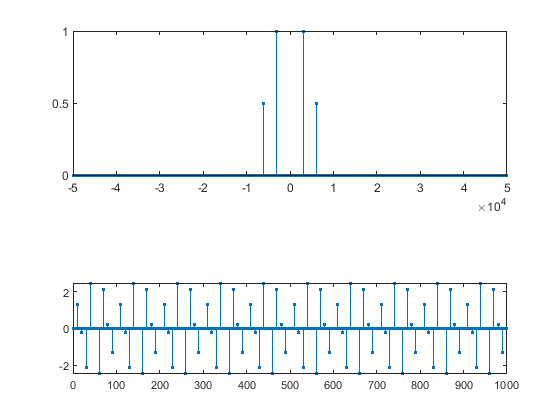

X_samplet = 10*(1/N)*fftshift(fft(x_samplet,N));
subplot(2,1,1)
stem(f,abs(X_analog),'.')

subplot(2,1,2)
stem(f,abs(X_samplet),'.')

**Definition af rekonstruktions-LPF:**

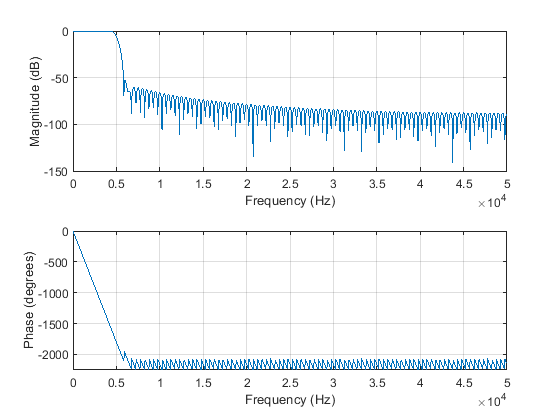

filterorden = 200;
normeret_knaekfrekvens = (fs/2) / (f_uendelig/2);
rekonstr_filter = fir1(filterorden,normeret_knaekfrekvens);
freqz(rekonstr_filter,1,1024,f_uendelig)

**Ideel rekonstruktion (eller forsøg på samme):**

x_rekonstr = filter(rekonstr_filter,1,x_samplet);

**Plot af analogt, samplet og rekonstrueret signal i frekvensdomænet:**

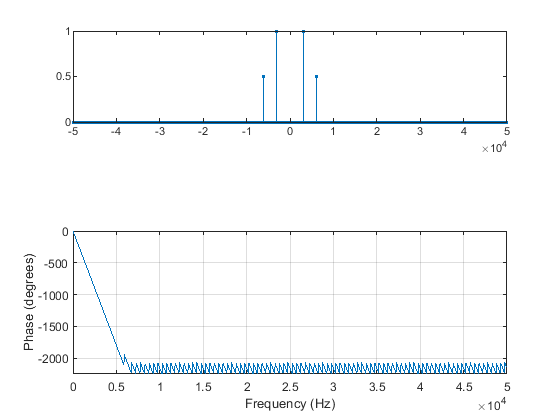

X_rekonstr = 10*(1/N)*fftshift(fft(x_rekonstr,N));
subplot(3,1,1)
stem(f,abs(X_analog),'.')

subplot(3,1,2)
stem(f,abs(X_samplet),'.')
subplot(3,1,3)
stem(f,abs(X_rekonstr),'.')

**Definition af anti-aliasing-LPF:**

For at undgå de konstaterede aliasing-problemer, må det analoge signal båndbegrænses vha. lavpasfilterering inden den ideelle sampling. Her anvendes et LFP med knækfrekvens fs/2.

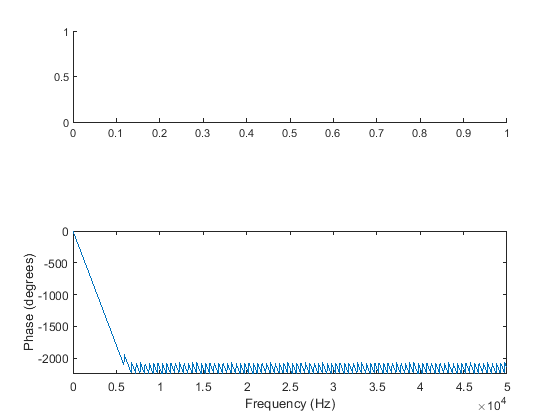

filterorden = 200;
normeret_knaekfrekvens = (fs/2)/(f_uendelig/2);
antialiasing_filter = fir1(filterorden,normeret_knaekfrekvens);
freqz(antialiasing_filter,1,1024,f_uendelig);

**Lavpasfiltrering af analogt signal med AA-LFP:**

x_analog_LP = filter(antialiasing_filter,1,x_analog);

**Plot af lavpasfiltreret analogt signal i tidsdomænet og frekvensdomænet:**

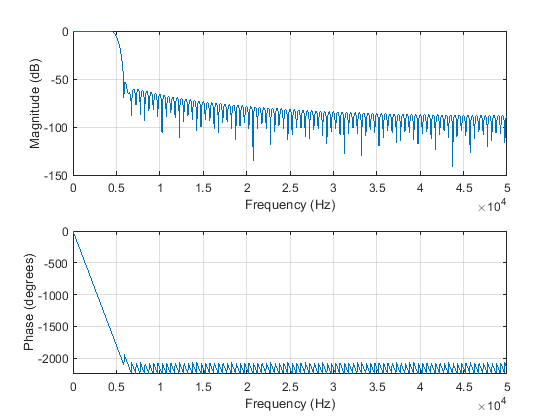

subplot(2,1,1)

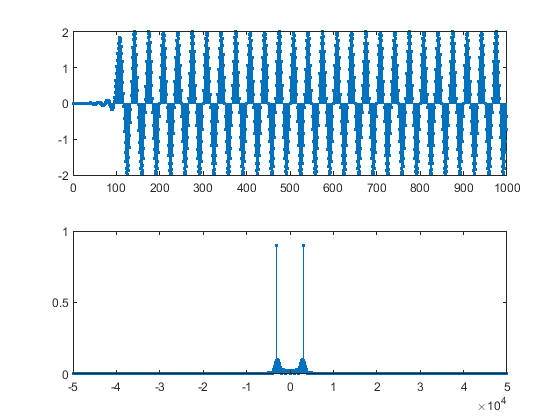

stem(n,x_analog_LP,'.')
subplot(2,1,2)
X_analog_LP = (1/N)*fftshift(fft(x_analog_LP,N));
k = (-N/2):(N/2-1);
f = k*f_uendelig/N;
stem(f,abs(X_analog_LP),'.')